# Gorilla mono-energetic transport coefficient

The Gorilla code can calculate the mono-energetic radial transport coefficient for particles in a fusion reactor. For this the 'mono_energetic_transp_main.x ' file is used. With that it is possible to calculate the fluxtube volume for a specified fusion devies and a defined grid. With the fluxtube volume the mono-energetic transport coefficient can be calculated for a given collisionality and mach number. It is also possible to scan over diffrent collisionalities. 

In this script the Gorilla code is used to calculate the mono-energetic transport coefficient for different collisionalites and for different mach number. All possible input variabels will be shown in this file. After the calcutlation MATLAB creates a plot for the transport coefficient over the normalized collisionality. 

## Initialization

First the MATLAB code needs to know where to find the used files. Therefor it is necessary to specify some paths. If the folder of Gorilla is unchanged and the current folder of MATLAB is the folder of this MATLAB script the default values should work. 

First the path of the MATLAB script:

path_script=pwd;
%default: path_script=pwd;

The path of the main folder of the GORILLA code:

path_main=[path_script,'/../'];
%default: path_main=[path_script,'/../'];

The path where the FORTRAN code should be execute:

mkdir(path_main,'RUN/mono_energetic_transport');

path_RUN=[path_main,'RUN/mono_energetic_transport'];
%default path_RUN=[path_main,'/RUN/mono_energetic_transport'];
cd(path_RUN);

In the inp_blueprint folder the inputfiles for the GORILLA code are already prepared. All input variables have a default value. These input files will be loaded into the MATLAB script later on.

path_inp_blueprints=[path_main,'/inp_blueprints'];
%default path_inp_blueprints=[path_main,'/inp_blueprints'];
addpath(path_inp_blueprints);

Some parts of the script are shifted to functions. Those function are stored in an own folder.

path_functions=[path_main,'MATLAB/functions'];
%default path_functions=[path_main,'/matlab_test_cases/functions'];
addpath(path_functions);

The created files during this run will be stored in an own folder. The code while create a new folder if the folder thus not exist.

name_folder='data_plots/mono_energetic_transport';
mkdir(path_script,name_folder);
path_data_plots=[path_script,'/',name_folder];

## Inputvariables

The GORILLA code works with some inputfiles. All possible options for the code can be set in this files. In the inp_blueprints folder there are default inputfiles already created. In this files one can also find short explanations for ervery variable. In this script all inputfiles will be load. The function Inputfile creates an object for every inputfile.

gorilla = InputFile([path_inp_blueprints,'/gorilla.inp']);
tetra_grid = InputFile([path_inp_blueprints,'/tetra_grid.inp']);
mono_energetic_transp_coef = InputFile([path_inp_blueprints,'/mono_energetic_transp_coef.inp']);

With the read methode all inputvariables from the inputfiles are loaded into the script. With that it is possible to change all settings wih this script. If a varibale is not changed inside this script, than the program uses the default value out of the inp_blueprints folder.

gorilla.read();
mono_energetic_transp_coef.read();
tetra_grid.read();

The code needs to be executed seperatly for diffrent normalized ExB-drifts (mach numbers).

mach_number = [0,10^-4];
%mach_number = [0,10^-4,10^-2];

## Inputfile gorilla

Electrostatic potential

Change in the electrostatic potential within the plasma volume in Gaussian units

gorilla.GORILLANML.eps_Phi = 0;

Coordinate system

    1 ... (R,phi,Z) cylindrical coordinate system

    2 ... (s,theta,phi) symmetry flux coordinate system 

gorilla.GORILLANML.coord_system = 2;

 Particle species

    1 ... electron

    2 ... deuterium ion

    3 ... alpha particle

gorilla.GORILLANML.ispecies = 3;

 Switch for initial periodic coordinate particle re-location (modulo operation)

    true ... Particles are re-located at initialization in the case of a periodic coordinate, if they are outside the computation domain.

    false .. Particles are not re-located at initialization (This might lead to error if particles are outside the computation domain)

gorilla.GORILLANML.boole_periodic_relocation = true;

 Gorilla pusher options

    1 ... numerical RK pusher

    2 ... polynomial pusher

gorilla.GORILLANML.ipusher = 2;

Numerical pusher options

    accuracy for integration step:

        false ... RK4

        true ... adaptive ODE45

gorilla.GORILLANML.boole_pusher_ode45 = false;

    ODE45 relative accuracy (pusher_orbit)

gorilla.GORILLANML.rel_err_ode45 = 1*10-8;

    Physical time - orbit parameter relation

        false ... dt_dtau is a linear function of position in each tetrahedron

        true ... dt_dtau is a constant averaged quantity in each tetrahedron

gorilla.GORILLANML.boole_dt_dtau = true;

    Precomputation for Newton iterations

        false ... Compute coefficients for 2nd order polynomial solution (Newton velocity and acceleration) in each tetrahedron (dzdtau) without precomputation

        true ... Use precomputation of coefficients for 2nd order polynomial solution (Newton velocity and acceleration)

gorilla.GORILLANML.boole_newton_precalc = false;

Polynomial pusher options

    Polynomial order for orbit pusher

gorilla.GORILLANML.poly_order = 4;

    Settings for precomputation of coefficients

        0 ... No precomputation: All coefficients are computed on the fly (power of matrices)

        1 ... Precomputation of coefficients and factorization of powers of perpinv

        2 ... Same as 1 but with further precomputation of operatorb in b

        3 ... Extended precomputation of coefficients for constant perpinv

        (Precomputation is done for each tetrahedron for constant perpinv) NOT IMPLEMENTED YET

gorilla.GORILLANML.i_precomp = 0;

    Face prediction with 2nd order polynomial

        true ... Face guessing algorithm is used

        false ... NOT used

gorilla.GORILLANML.boole_guess = true;

 Processing of particle handover to tetrahedron neighbour

    1 ... Processing with special treatment of periodic boundaries and manipulation of periodic position values

    2 ... Position exchange via Cartesian variables (skew_coordinates) - Necessary precomputation is included

gorilla.GORILLANML.handover_processing_kind = 1;

Multiple options to manipulate the axisymmetric electromagnetic field (Tokamak) with noise

    Add axisymmetric random noise (\xi = 0 ... 1) to the co-variant component of the vector potential $A_k$

    $A_k = A_k (1+\epsilon_A \xi)$ 

gorilla.GORILLANML.boole_axi_noise_vector_pot = false;

    Relative Magnitude of axisymmetric random noise $\epsilon_A$ of vector potential

gorilla.GORILLANML.axi_noise_eps_A = 0.1;

    Add axisymmetric random noise to the electrostatic potential $\Phi$

    $\Phi = \Phi (1+\epsilon_\Phi \xi)$,

gorilla.GORILLANML.boole_axi_noise_elec_pot = false;

    Relative Magnitude of axisymmetric random noise $\epsilon_\Phi$ of electrostatic potential

gorilla.GORILLANML.axi_noise_eps_Phi = 0.3;

    Add non-axisymmetric random noise to the co-variant component of the vector potential $A_k$

gorilla.GORILLANML.boole_non_axi_noise_vector_pot = false;

    Relative Magnitude of non-axisymmetric random noise $\epsilon_A$ of vector potential

gorilla.GORILLANML.non_axi_noise_eps_A = 1*10-4;

Manipulation of the axisymmetric electromagnetic field (Tokamak) with helical harmonic perturbation

    Switch for helical harmonic perturbation of A_phi

        false ... no perturbation

        true ... perturbation on: A_phi = A_phi + A_phi*helical_pert_eps_Aphi * cos(m_fourier*theta +n_fourier*phi)

gorilla.GORILLANML.boole_helical_pert = false;

    Amplitude for helical harmonic perturbation

gorilla.GORILLANML.helical_pert_eps_Aphi = 0.1;

    Fourier modes of helical perturbation

 gorilla.GORILLANML.helical_pert_m_fourier = 2;
 gorilla.GORILLANML.helical_pert_n_fourier = 2;

### Inputfile terta_grid

Grid Size:

    Rectangular: nR, Field-aligned: ns

tetra_grid.TETRA_GRID_NML.n1 = 10;

    Rectangular: nphi, Field-aligned: nphi

tetra_grid.TETRA_GRID_NML.n2 = 10;

    Rectangular: nZ, Field-aligned: ntheta

tetra_grid.TETRA_GRID_NML.n3 = 10;

Grid kind:

     1 ... rectangular grid for axisymmetric EFIT data

     2 ... field-aligned grid for axisymmetric EFIT data

     3 ... field-aligned grid for non-axisymmetric VMEC

tetra_grid.TETRA_GRID_NML.grid_kind = 3;

Switch for selecting number of field periods automatically or manually

    true ... number of field periods is selected automatically (Tokamak = 1,       Stellarator depending on VMEC equilibrium)

    false ... number of field periods is selected manually (see below)

tetra_grid.TETRA_GRID_NML.boole_n_field_periods = true;

Number of field periods (manual)

tetra_grid.TETRA_GRID_NML.n_field_periods_manual = 1;

Symmetry Flux Coordinates Annulus (Minimal value for flux coordinates s)

tetra_grid.TETRA_GRID_NML.sfc_s_min = 0.1;

Option for $\theta$-variable being used in grid

    1 ... theta scaling in symmetry flux coordinates

    2 ... theta scaling in geometrical theta angle 

tetra_grid.TETRA_GRID_NML.theta_geom_flux = 1;

Option for $\theta$-variable origin

    true ... $\theta$-variable starts at the line between O- and X-Point

    false ... $\theta$-variable starts at the line between O-Point and intersection between O-Point-[1,0]-straight-line and separatrix

tetra_grid.TETRA_GRID_NML.theta0_at_xpoint = false;

Switch for writing object file with mesh data

tetra_grid.TETRA_GRID_NML.boole_write_mesh_obj = false;

 Filename for mesh object file in cylindrical coordintes

tetra_grid.TETRA_GRID_NML.filename_mesh_rphiz = 'mesh_rphiz.obj';

Filename for mesh object file in symmetry flux coordintes 

tetra_grid.TETRA_GRID_NML.filename_mesh_sthetaphi = 'mesh_sthetaphi.obj';

### Inputfile mono_ernergetic_transp

Fluxtube volume OR mono-energetic radial transport coefficient OR numerical diffusion coefficient

    1 ... Pre-computation of fluxtube volume for GORILLA

    2 ... Computation of mono-energetic transport coefficient for given collisionality and Mach number

    3 ... Scan over collisionality: Computation of mono-energetic transport coefficent for constant Mach number

    4 ... Computation of numerical diffusion coefficient (No collisions)

mono_energetic_transp_coef.TRANSPCOEFNML.i_option = 3;

Options for pre-computation of fluxtube volume

    Filname of the fluxtube volume to be precomputed

mono_energetic_transp_coef.TRANSPCOEFNML.filename_fluxtv_precomp = 'fluxtubevolume.dat';

    Starting value for drift surface

        = s for (s,$\vartheta$,$\varphi$)

        = R for (R,$\varphi$,Z)

mono_energetic_transp_coef.TRANSPCOEFNML.start_pos_x1 = 0.6;

    Starting value for toroidal variable

        = $\vartheta$ for (s,$\vartheta$,$\varphi$)

        = $\varphi$ for (R,$\varphi$,Z)

mono_energetic_transp_coef.TRANSPCOEFNML.start_pos_x2  = 0.00013;

    Starting value for poloidal variable $\vartheta$

        = $\varphi$ for (s,$\vartheta$,$\varphi$)

        = Z for (R,$\varphi$,Z)

mono_energetic_transp_coef.TRANSPCOEFNML.start_pos_x3  = 0.00013;

    Size of a single time step

mono_energetic_transp_coef.TRANSPCOEFNML.t_step_fluxtv = 0.001;

    Number of time steps for fluxtube volume

mono_energetic_transp_coef.TRANSPCOEFNML.nt_steps_fluxtv = 10000;

    Kinetic particle energy (in eV) for fluxtube volume computation

mono_energetic_transp_coef.TRANSPCOEFNML.energy_eV_fluxtv = 3000;

Settings of simulation for transport coefficients

    Type of integrator for transport coefficient computation

        0 ... No trajectory integration (for measuring overhead computation time)

        1 ... GORILLA

        2 ... Direct Integrator in VMEC coordinates

mono_energetic_transp_coef.TRANSPCOEFNML.i_integrator_type = 1;

    Number of particles for Monte Carlo simulation

mono_energetic_transp_coef.TRANSPCOEFNML.n_particles = 200;

    Model diffusion with collisions

        false ... without collisions

        true ... with collisions (Lorentz collision operator)

mono_energetic_transp_coef.TRANSPCOEFNML.boole_collisions = true;

    Kinetic particle energy (in eV)

mono_energetic_transp_coef.TRANSPCOEFNML.energy_eV = 6*10^6;

    Filname of the fluxtube volume to be loaded for starting positions of MC simulation

mono_energetic_transp_coef.TRANSPCOEFNML.filename_fluxtv_load = 'fluxtubevolume.dat';

    Option for computation of evolution of $\psi$ (flux)

        true ... Full evolution of $\psi$ for every particle is saved in memory (psi_mat)

        false ... Evolution of $\psi$ for a single particle is NOT saved in memory

mono_energetic_transp_coef.TRANSPCOEFNML.boole_psi_mat = false;

Settings for random numbers to model collisions

    Precomputation of random numbers for pitch angle scattering

        false ... random numbers are calculated on the fly

        true ... random numbers are precomputed

mono_energetic_transp_coef.TRANSPCOEFNML.boole_random_precalc = true;

    Option for precomputation of above random numbers

        1 ... compute seed with a random number

        2 ... load seed from file 'seed.dat'

mono_energetic_transp_coef.TRANSPCOEFNML.seed_option = 2;

Settings for output of diffusion coefficient and standard deviation of diffusion coefficient

    Write raw data of trend of $(\Delta s)^2$ and deviation OR computation of transport coefficient in Fortran

        1 ... Fortran computation of linear interpolation with least squares (Diffusion coefficient and deviation of mean value)

        2 ... Output of RAW data and further processing with Matlab

        3 ... BOTH 1 & 2

mono_energetic_transp_coef.TRANSPCOEFNML.idiffcoef_output = 3;

    Filename for evolution of mean value of $(\Delta s)^2$

mono_energetic_transp_coef.TRANSPCOEFNML.filename_delta_s_squared = ['psi2_v_E_',num2str(mach_number(1)),'.dat'];

    Filename for evolution of standard deviation of mean value of $(\Delta s)^2$

mono_energetic_transp_coef.TRANSPCOEFNML.filename_std_dvt_delta_s_squared = ['std_psi2_v_E_',num2str(mach_number(1)),'.dat'];

Settings for mono-energetic transport coefficient for given collisionality and Mach number

    Filename for Fortran computation of diffusion coefficient and deviation of mean value (Transport with collisions)

mono_energetic_transp_coef.TRANSPCOEFNML.filename_transp_diff_coef = ['nustar_diffcoef_std_v_E_',num2str(mach_number(1)),'.dat'];

    Normalized collisionality $\nu^\ast$   

 mono_energetic_transp_coef.TRANSPCOEFNML.nu_star = 0.1;

    Normalized ExB-drift velocity $v_E$ (Mach number)

 mono_energetic_transp_coef.TRANSPCOEFNML.v_E = mach_number(1);

Settings for scan over collisionality: Mono-energetic transport coefficent for constant Mach number (from above)

    Starting value for normalized collisionality $\nu^\ast$ (Highest value --> Scan is towards smaller collisionalities)

mono_energetic_transp_coef.TRANSPCOEFNML.nu_star_start = 0.1;

    Basis of negative exponential scan: nu_star = nu_star_start * nu_exp_basis^i

mono_energetic_transp_coef.TRANSPCOEFNML.nu_exp_basis = 0.5;

    Number of evaluations of nu_star for scan

mono_energetic_transp_coef.TRANSPCOEFNML.n_nu_scans = 3;

Settings for numerical diffusion coefficient (no collisions)

    Filename for Fortran computation of diffusion coefficient and deviation of mean value (numerical diffusion without collisions)

mono_energetic_transp_coef.TRANSPCOEFNML.filename_numerical_diff_coef = 'numerical_diffcoef_std.dat';

    Pitchparameter $\lambda = v_\parallel/v$ at the start for numerical diffusion coefficient

mono_energetic_transp_coef.TRANSPCOEFNML.lambda_start = 0.9;

    Total Monte Carlo physical orbit flight time per particle

mono_energetic_transp_coef.TRANSPCOEFNML.total_MC_time = 10;

    Number of time steps for evolution of $(\Delta s)^2$

mono_energetic_transp_coef.TRANSPCOEFNML.nt_steps_numerical_diff = 10000;

The write methode creates new inputfiles, with the change variables, in the RUN folder.

gorilla.write([path_RUN,'/gorilla.inp']);
tetra_grid.write([path_RUN,'/tetra_grid.inp']);
mono_energetic_transp_coef.write([path_RUN,'/mono_energetic_transp_coef.inp']);

## Execute GORILLA

First all necessary files need to be linked to the RUN folder

! ln -s ../../mono_energetic_transp_main.x .

ln: failed to create symbolic link './mono_energetic_transp_main.x': File exists


! ln -s ../../DATA .

ln: failed to create symbolic link './DATA': File exists


! ln -s DATA/VMEC/netcdf_file_for_test.nc .

ln: failed to create symbolic link './netcdf_file_for_test.nc': File exists


! ln -s DATA/VMEC/netcdf_file_for_test_6.nc .

ln: failed to create symbolic link './netcdf_file_for_test_6.nc': File exists


! ln -s ../../inp_blueprints/field_divB0.inp .

ln: failed to create symbolic link './field_divB0.inp': File exists


! ln -s ../../inp_blueprints/preload_for_SYNCH.inp .

ln: failed to create symbolic link './preload_for_SYNCH.inp': File exists


! ln -s ../../inp_blueprints/seed.inp .

ln: failed to create symbolic link './seed.inp': File exists


% ! ln -s ../../DATA/btor_rbig.dat
% ! ln -s ../../DATA/flux_functions.dat
% ! ln -s ../../DATA/box_size_axis.dat
% ! ln -s ../../DATA/twodim_functions.dat
% ! ln -s ../../DATA/out.06

If there is already a file for the fluxtube volume with the specified name form above in the execution folder, the sricpt will check whether the file can be used for the current calculation. If this is not the case, this sricpt will use the Gorilla code to create a new file for the fluxtube volume. All necessary input settings for that will be taken from above. 

try
    fluxtubevolume_file = fopen(mono_energetic_transp_coef.TRANSPCOEFNML.filename_fluxtv_load);
    fluxtubevolume_line1 = str2num(fgetl(fluxtubevolume_file));
    fluxtubevolume_line2 = str2num(fgetl(fluxtubevolume_file));
    fclose(fluxtubevolume_file);
    fluxtubevolume_L = false(1,5);
    fluxtubevolume_L(1) = tetra_grid.TETRA_GRID_NML.grid_kind == fluxtubevolume_line2(1);
    fluxtubevolume_L(2) = gorilla.GORILLANML.coord_system == fluxtubevolume_line2(2);
    fluxtubevolume_L(3) = tetra_grid.TETRA_GRID_NML.n1 == fluxtubevolume_line2(3);
    fluxtubevolume_L(4) = tetra_grid.TETRA_GRID_NML.n2 == fluxtubevolume_line2(4);
    fluxtubevolume_L(5) = tetra_grid.TETRA_GRID_NML.n3 == fluxtubevolume_line2(5);
    if any(~fluxtubevolume_L) == true
        disp('The file for the fluxtubevolume does not agree with the specified input variables');
        error();
    end
catch
    disp('Could not find correct fluxtubevolume file')
    disp('Calculated new fluxtubevolumes');
    mono_energetic_transp_coef.TRANSPCOEFNML.filename_fluxtv_precomp = mono_energetic_transp_coef.TRANSPCOEFNML.filename_fluxtv_load;
    ispecies = gorilla.GORILLANML.ispecies;
    gorilla.GORILLANML.ispecies = 1;
    i_option = mono_energetic_transp_coef.TRANSPCOEFNML.i_option;
    mono_energetic_transp_coef.TRANSPCOEFNML.i_option = 1;
    gorilla.write([path_RUN,'/gorilla.inp']);
    mono_energetic_transp_coef.write([path_RUN,'/mono_energetic_transp_coef.inp']);
    %return
    ! ./mono_energetic_transp_main.x
    gorilla.GORILLANML.ispecies = ispecies;
    mono_energetic_transp_coef.TRANSPCOEFNML.i_option = i_option;
    gorilla.write([path_RUN,'/gorilla.inp']);
    mono_energetic_transp_coef.write([path_RUN,'/mono_energetic_transp_coef.inp']);
end

Could not find correct fluxtubevolume file


Calculated new fluxtubevolumes


./mono_energetic_transp_main.x: /afs/itp.tugraz.at/opt/matlab/2021b/sys/os/glnxa64/libgfortran.so.5: version `GFORTRAN_10' not found (required by ./mono_energetic_transp_main.x)
./mono_energetic_transp_main.x: /afs/itp.tugraz.at/opt/matlab/2021b/sys/os/glnxa64/libgfortran.so.5: version `GFORTRAN_10' not found (required by /usr/lib/x86_64-linux-gnu/libnetcdff.so.7)


After the fluxtube volume file is created the main part of the calculation can be started. 

%return
! ./mono_energetic_transp_main.x

./mono_energetic_transp_main.x: /afs/itp.tugraz.at/opt/matlab/2021b/sys/os/glnxa64/libgfortran.so.5: version `GFORTRAN_10' not found (required by ./mono_energetic_transp_main.x)
./mono_energetic_transp_main.x: /afs/itp.tugraz.at/opt/matlab/2021b/sys/os/glnxa64/libgfortran.so.5: version `GFORTRAN_10' not found (required by /usr/lib/x86_64-linux-gnu/libnetcdff.so.7)


The function 'load_copy_transport_coef' copys every created data file to the specified folder and loads the data into this script. The names of the variables are equal to the file names (inside the data structure).

data=struct();
data=load_copy_transport_coef(data,path_RUN,path_data_plots,mono_energetic_transp_coef);

For every mach number the Gorilla code needs to be started separately. To store the created data in different files the names of the files are change for every mach number.

for i=2:numel(mach_number)
    mono_energetic_transp_coef.TRANSPCOEFNML.v_E = mach_number(i);
    
    mono_energetic_transp_coef.TRANSPCOEFNML.filename_delta_s_squared = ['psi2_v_E_',num2str(mach_number(i)),'.dat'];
    mono_energetic_transp_coef.TRANSPCOEFNML.filename_std_dvt_delta_s_squared = ['std_psi2_v_E_',num2str(mach_number(i)),'.dat'];
    mono_energetic_transp_coef.TRANSPCOEFNML.filename_transp_diff_coef = ['nustar_diffcoef_std_v_E_',num2str(mach_number(i)),'.dat'];
    
    mono_energetic_transp_coef.write([path_RUN,'/mono_energetic_transp_coef.inp']);
    %return
    ! ./mono_energetic_transp_main.x
    
    data=load_copy_transport_coef(data,path_RUN,path_data_plots,mono_energetic_transp_coef);
end

./mono_energetic_transp_main.x: /afs/itp.tugraz.at/opt/matlab/2021b/sys/os/glnxa64/libgfortran.so.5: version `GFORTRAN_10' not found (required by ./mono_energetic_transp_main.x)
./mono_energetic_transp_main.x: /afs/itp.tugraz.at/opt/matlab/2021b/sys/os/glnxa64/libgfortran.so.5: version `GFORTRAN_10' not found (required by /usr/lib/x86_64-linux-gnu/libnetcdff.so.7)


After the end of the GORILLA run the current folder should be again the folder of the script. 

cd(path_script);

## Create Plots

 If the inputvarible 'mono_energetic_transp_coef.TRANSPCOEFNML.idiffcoef_output' is 1 or 3, the GORILLA code calculates the diffusion coefficient with a linear interpolation with least squares. The result is than plotted with MATLAB in an double logarithmic plot. Every curve in the plot represents one mach number.

If the inputvarible 'mono_energetic_transp_coef.TRANSPCOEFNML.idiffcoef_output' is 2 or 3, the GORILLA code writes the mean vlaue of /Delta s in an output file. MATLAB than creates an own plot for every mach number and for every \nu_star value. In all this plots the data should lie on a linear curve. Outherwise the data is not trustworth. 

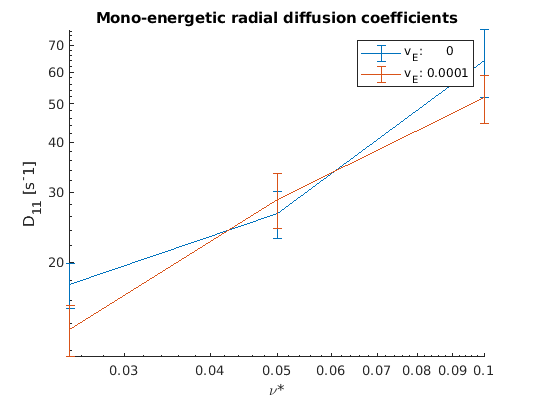

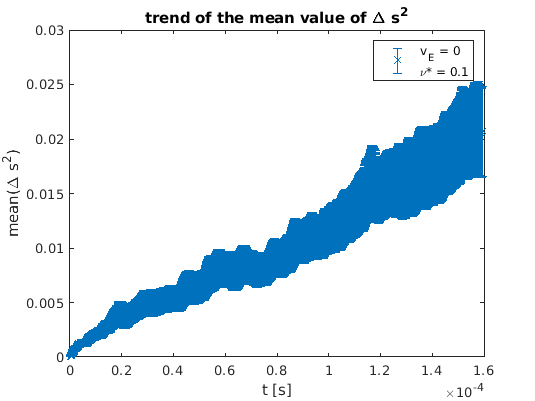

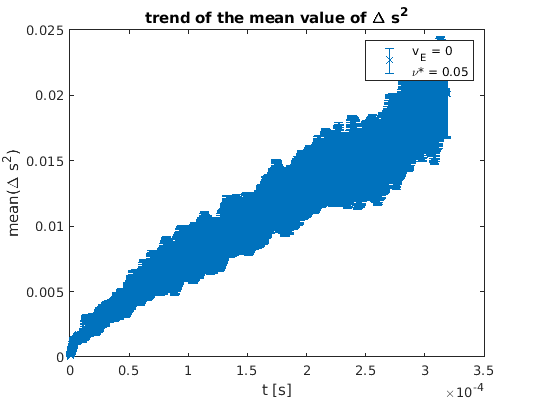

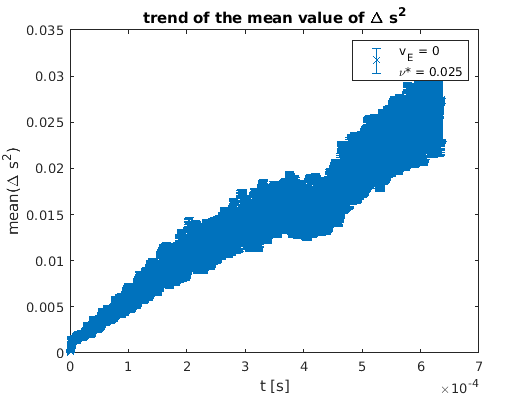

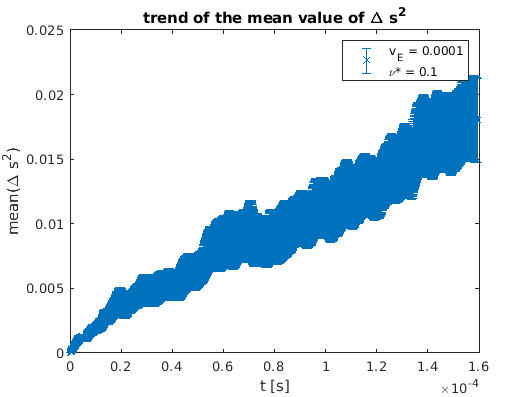

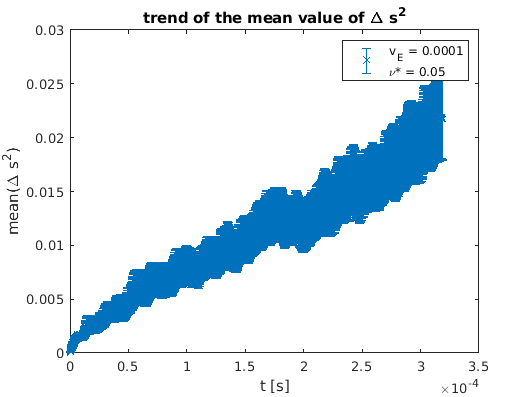

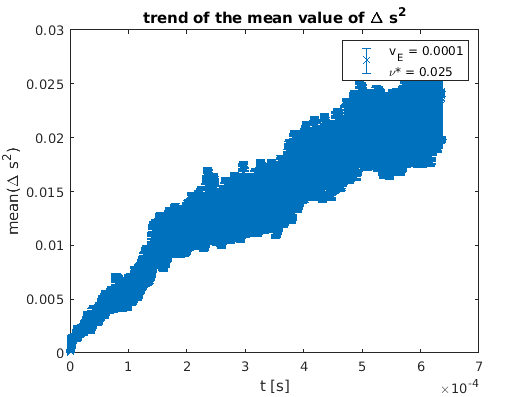

if mono_energetic_transp_coef.TRANSPCOEFNML.idiffcoef_output == 1
    names=fieldnames(data);
    figure
    hold on
    for i=1:numel(names)
        errorbar(data.(names{i})(:,1),data.(names{i})(:,2),data.(names{i})(:,3).*1.96)
    end
    title('Mono-energetic radial diffusion coefficients');
    legend([repmat('v_E: ',numel(mach_number),1),num2str(mach_number')])
    xlabel('\nu*');
    ylabel('D_{11} [s^-1]');
    set(gca,'xscale','log','yscale','log');
    hold off
    savefig([path_data_plots,'/diffusion_coefficients.fig']);
    saveas(gcf,[path_data_plots,'/diffusion_coefficients.png']);
elseif mono_energetic_transp_coef.TRANSPCOEFNML.idiffcoef_output == 2
    names=fieldnames(data);
    for i=1:numel(names)/2
        empty_row=find(~data.(names{2*i-1})(:,1));
        empty_row=[0;empty_row];
        for j=1:numel(empty_row)-1
            j_data=empty_row(j)+1:empty_row(j+1)-1;
            figure
            errorbar(data.(names{2*i-1})(j_data,1),data.(names{2*i-1})(j_data,2),data.(names{2*i})(j_data,2).*1.96,'x')
            title('trend of the mean value of \Delta s^2');
            nu_star=mono_energetic_transp_coef.TRANSPCOEFNML.nu_star_start.*mono_energetic_transp_coef.TRANSPCOEFNML.nu_exp_basis.^(j-1);
            legend(['v_E = ',num2str(mach_number(i)),newline,'\nu* = ',num2str(nu_star)])
            xlabel('t [s]');
            ylabel('mean(\Delta s^2)')
            hold off
            savefig([path_data_plots,'/psi2_',num2str(i),'_',num2str(j),'.fig']);
            saveas(gcf,[path_data_plots,'/psi2_',num2str(i),'_',num2str(j),'.png']);
        end
    end
else
    names=fieldnames(data);
    figure
    hold on
    for i=1:numel(names)/3
        errorbar(data.(names{3*i-2})(:,1),data.(names{3*i-2})(:,2),data.(names{3*i-2})(:,3).*1.96)
    end
    title('Mono-energetic radial diffusion coefficients');
    legend([repmat('v_E: ',numel(mach_number),1),num2str(mach_number')])
    xlabel('\nu*');
    ylabel('D_{11} [s^-1]');
    set(gca,'xscale','log','yscale','log');
    hold off
    savefig([path_data_plots,'/diffusion_coefficients.fig']);
    saveas(gcf,[path_data_plots,'/diffusion_coefficients.png']);
    for i=1:numel(names)/3
        empty_row=find(~data.(names{3*i-1})(:,1));
        empty_row=[0;empty_row];
        for j=1:numel(empty_row)-1
            j_data=empty_row(j)+1:empty_row(j+1)-1;
            figure
            errorbar(data.(names{3*i-1})(j_data,1),data.(names{3*i-1})(j_data,2),data.(names{3*i})(j_data,2).*1.96,'x')
            title('trend of the mean value of \Delta s^2');
            nu_star=mono_energetic_transp_coef.TRANSPCOEFNML.nu_star_start.*mono_energetic_transp_coef.TRANSPCOEFNML.nu_exp_basis.^(j-1);
            legend(['v_E = ',num2str(mach_number(i)),newline,'\nu* = ',num2str(nu_star)])
            xlabel('t [s]');
            ylabel('mean(\Delta s^2)')
            hold off
            savefig([path_data_plots,'/psi2_',num2str(i),'_',num2str(j),'.fig']);
            saveas(gcf,[path_data_plots,'/psi2_',num2str(i),'_',num2str(j),'.png']);
        end
    end
end